# **Dynamics of Planar Mechanisms - Lab Work 2**

## Group Members:

- Ng'ethe Bernice         ENM221-0085/2017

- Vivian Mwangi            ENM221-0163/2017

- Dickson Mutura          ENM221-0082/2017

The striking mechanism of a weaving machine consists of a four bar linkage. In a particular case, such a linkage is required to coordinate five positions of the rocker follower with five positions of the input crank as shown in the Table 1. The length of the fixed link is required to be 180mm. 

Table 1:

S/NO.           Input angle, θ 2        Input angle, θ 4

 1.0              40                             70

 2.0              45                             76 

 3.0              50                             83

 4.0              55                             91     

 5.0              60                             100

 Write a computer program in MATLAB to, 

(a) Evaluate K1, K2 and K3 using the least square method, and hence determine the length of the other links 

(b) Calculate the transmission angles for the given range of input angles and at an increment of 1 degree , and plot a curve of the transmission angles against the input angles for the given range. Comment on the quality of transmission of the linkage. 

(c) Calculate the structural errors throughout the given range of input angles and at an increment of 1 degree . Plot a curve of the structural error against the input angles for the given range, and hence comment on the resulting error.

% positions of input crank
theta2 = 40:5:60

theta2 =     40    45    50    55    60



% positions of the rocker follower
theta4 = [70 76 83 91 100]

theta4 =     70    76    83    91   100


% create a matrix for the 5 simultaneous equations that are formed
% by substituting the 5 sets of input-output angles obtained above
% into Freudenstein's equation

% 'A' is a 5X3 matrix containing coeficients on the LHS of the equations
A = [cosd(theta4(1)) -cosd(theta2(1)) 1;     
      cosd(theta4(2)) -cosd(theta2(2)) 1;     
      cosd(theta4(3)) -cosd(theta2(3)) 1;
      cosd(theta4(4)) -cosd(theta2(4)) 1;
      cosd(theta4(5)) -cosd(theta2(5)) 1;]

A =     0.3420   -0.7660    1.0000
    0.2419   -0.7071    1.0000
    0.1219   -0.6428    1.0000
   -0.0175   -0.5736    1.0000
   -0.1736   -0.5000    1.0000



% 'B' is a 5X1 matrix containing coeficients on the RHS of the equations      
B = [cosd(theta2(1) - theta4(1));
      cosd(theta2(2) - theta4(2));
      cosd(theta2(3) - theta4(3));
      cosd(theta2(4) - theta4(4));
      cosd(theta2(5) - theta4(5))]

B =     0.8660
    0.8572
    0.8387
    0.8090
    0.7660


K = lsqr(A,B) % solve for the link ratios, K, using the least squares method

lsqr converged at iteration 3 to a solution with relative residual 0.0009.


K =     1.0201
    1.6053
    1.7464



K1 = K(1)

K1 = 1.0201

K2 = K(2)

K2 = 1.6053

K3 = K(3)

K3 = 1.7464

% Getting the lengths of the links as per the Freudenstein's equation
% All values are in mm
d = 180        % fixed linked- value was predefined in the question

d = 180

a = d/K1       % Input link

a = 176.4601

c = d/K2       % output link

c = 112.1312

b = sqrt(a^2 + c^2 + d^2 - (K3*2*a*c))   % coupler link

b = 83.6747

input_angles = 40:1:60 % input angles spaced at 1 degree

input_angles =     40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60



% obtain transmission angles using the formula below
mu = acosd(((b^2 + c^2) - (a^2 + d^2) + (2*a*d*cosd(input_angles))) / (2*b*c))

mu =    75.4945   77.7545   80.0406   82.3550   84.7004   87.0795   89.4953   91.9513   94.4512   96.9996   99.6012  102.2619  104.9882  107.7879  110.6703  113.6464  116.7298  119.9374  123.2905  126.8170  130.5544



min_mu = min(mu)    % get minimum transmission angle

min_mu = 75.4945

max_mu = max(mu)    % get maximum transmission angle

max_mu = 130.5544

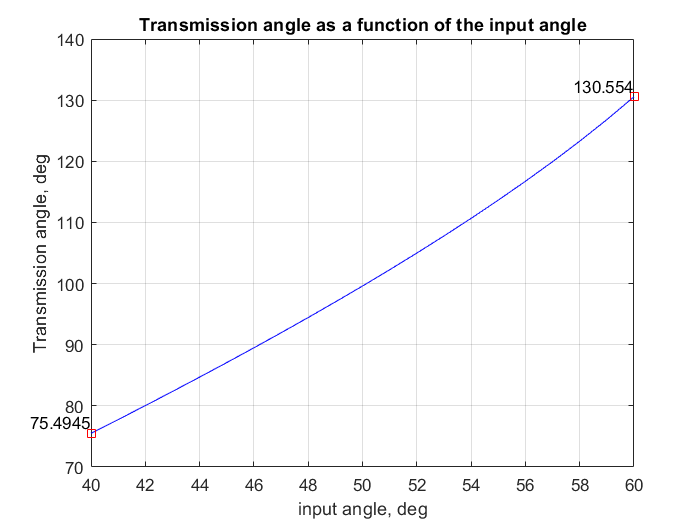

% plot transmission angle against input angle

plot(input_angles,mu,'b-')
hold on 

plot(input_angles(1), mu(1),'rs') % add square markers at the beginning and end of plot
hold on 

plot(input_angles(end), mu(end),'rs') % add max and min values of transmission angles to the plot
x = [input_angles(1) input_angles(end)];
y = [mu(1) mu(end)];
labels = {min_mu,max_mu};
text(x,y,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

title('Transmission angle as a function of the input angle')

xlabel('input angle, deg')

ylabel('Transmission angle, deg')

grid on

[row,column] = size(input_angles)

row = 1

column = 21

output_angles = linspace(70,100,column)

output_angles =    70.0000   71.5000   73.0000   74.5000   76.0000   77.5000   79.0000   80.5000   82.0000   83.5000   85.0000   86.5000   88.0000   89.5000   91.0000   92.5000   94.0000   95.5000   97.0000   98.5000  100.0000


% get a range of output angles from the given input angles
 % e represents values obtained from link ratios 
e = (K1*cosd(output_angles)) - (K2*cosd(input_angles) + K3 - cosd(input_angles - output_angles))

e =    -1.7612   -1.7726   -1.7839   -1.7952   -1.8063   -1.8173   -1.8282   -1.8389   -1.8495   -1.8599   -1.8702   -1.8802   -1.8901   -1.8997   -1.9091   -1.9183   -1.9272   -1.9358   -1.9442   -1.9523   -1.9601


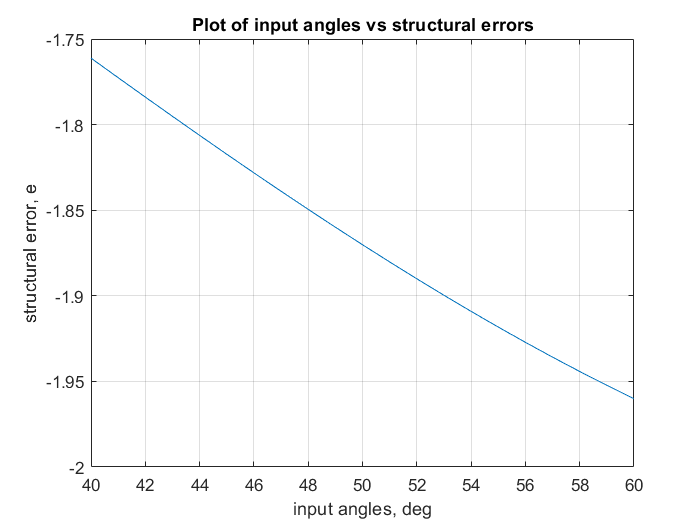

% plot structural errors as a function of input angles
plot(input_angles,e)

grid on
title('Plot of input angles vs structural errors')
xlabel('input angles, deg')
ylabel('structural error, e')